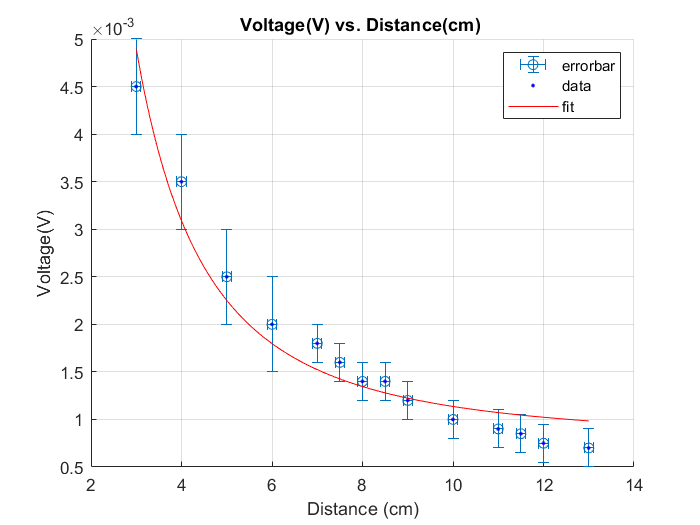

[xData, yData] = prepareCurveData( dist, voltage );
distanceerr=[0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1];
volterr=[0.5 0.5 0.5 0.5 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2].*10^(-3);

% Set up fittype and options.
ft = fittype( 'a*x^(-2)+b', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.957166948242946 0.485375648722841];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );
xneg=distanceerr;
xpos=distanceerr;
yneg=volterr;
ypos=yneg;
% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
errorbar(dist,voltage,yneg,ypos,xneg,xpos,'o')
h = plot( fitresult, xData, yData );

grid on
legend({'errorbar', 'data','fit'})
title('Voltage(V) vs. Distance(cm) ')
xlabel('Distance (cm)')
ylabel('Voltage(V)')
hold off

General model:

     f(x) = a*x^(-2)+b

Coefficients (with 67% confidence bounds):

       a =      0.0402  \pm0.0072 

       b =   0.0006765  \pm0.0000711 

Goodness of fit:

  SSE: 7.906e-07

  R-square: 0.9574

  Adjusted R-square: 0.9511

  RMSE: 0.0002585

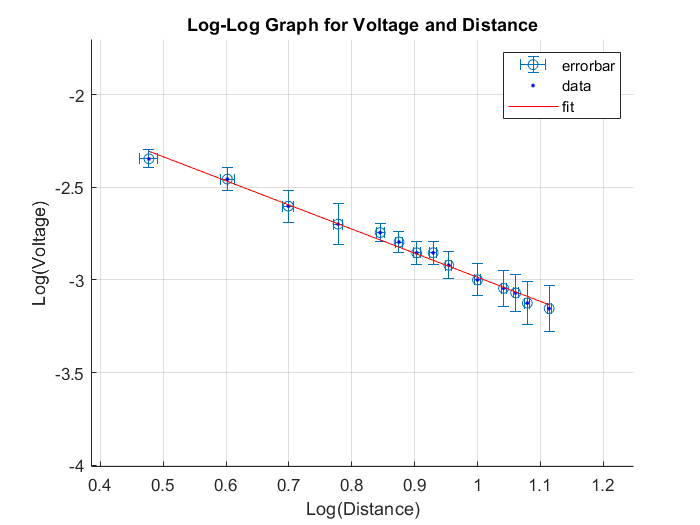

distlogerr=((distanceerr./(log(10)*dist)));
voltlogerr=((volterr./(log(10)*voltage)));

xneg=distlogerr;
xpos=distlogerr;
yneg=voltlogerr;
ypos=yneg;


[xData, yData] = prepareCurveData( logD, logV );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
errorbar(logD,logV,yneg,ypos,xneg,xpos,'o')
h = plot( fitresult, xData, yData );
xlim([0.385 1.249])
ylim([-4.01 -1.70])
grid on

title('Log-Log Graph for Voltage and Distance')
xlabel('Log(Distance)')
ylabel('Log(Voltage)')
legend({'errorbar','data','fit'})
hold off

Linear model Poly1:

     f(x) = p1*x + p2

Coefficients (with 95% confidence bounds):

       p1 =      -1.321 \pm0.031 

       p2 =      -1.655 \pm0.052 

Goodness of fit:

  SSE: 0.008024

  R-square: 0.9904

  Adjusted R-square: 0.9898

  RMSE: 0.02571